## v0 Intro

In this scrip we try to use svd to process the cutted experiment data, and figure out the property at the same time.

## Loading and pre-treatment data

%for5s name_list=["n78","n142","p47","p77","p179"];
%for30s name_list=["n78","n142","n589","p47","p77","p179"];
name_list=["n78","n142","p47","p77","p179"]

name_list = 1×5 string 数组
    "n78"    "n142"    "p47"    "p77"    "p179"


experiment_interval=5;%s
matrix_processed_MSD=[];
min_length=100;
for i=1:length(name_list)
    name=char(name_list(i));
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',name,'_',num2str(experiment_interval),'s.mat'])
    min_length=min(reserved_length,min_length);
end
for i=1:length(name_list)
    name=char(name_list(i));
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',name,'_',num2str(experiment_interval),'s.mat'])
    matrix_processed_MSD=[matrix_processed_MSD;processed_MSD(1:min_length).'];
end

## Calculate svd

[U,S,V]=svd(matrix_processed_MSD);
singular_value=[];
reserved_S=zeros(length(name_list),min_length);
for i=1:length(name_list)
    singular_value=[singular_value,S(i,i)];
    if i<=2
        reserved_S(i,i)=S(i,i);
    end
end
disp(singular_value)

   1.0e+06 *

    3.0563    0.0787    0.0167    0.0092    0.0069



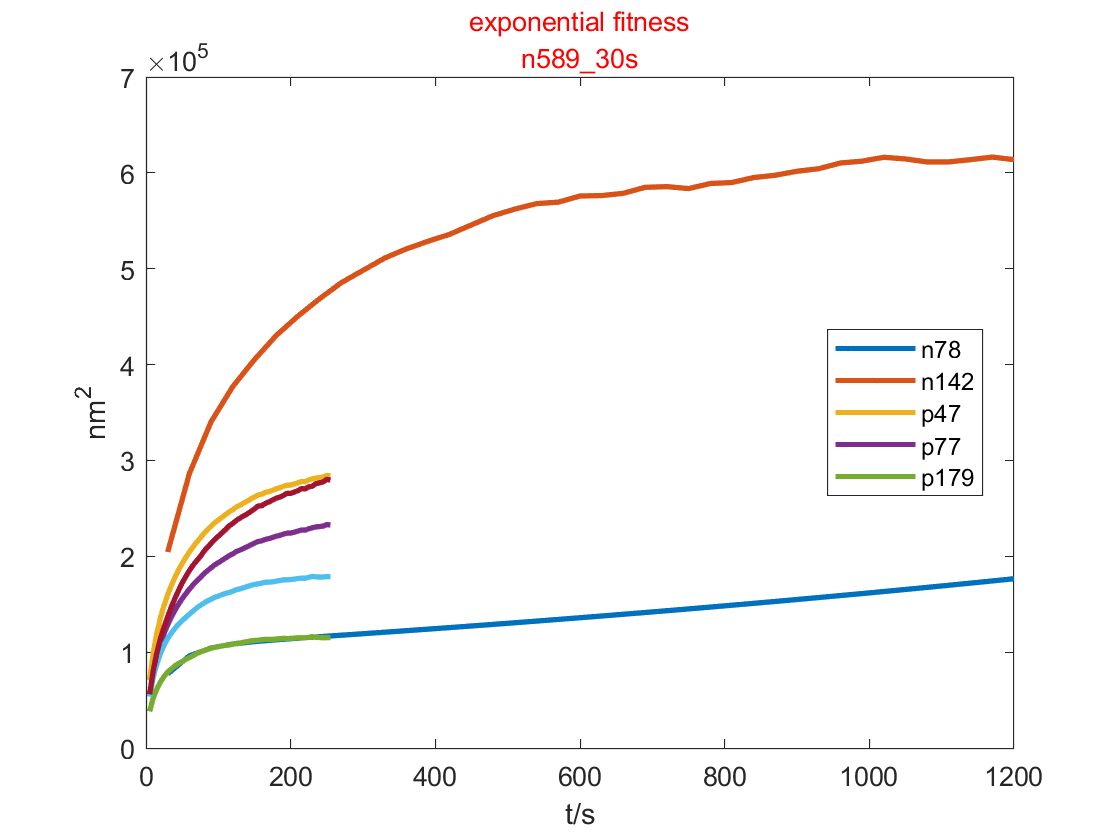

smoothed_curve=U*reserved_S*V';
time_scale=experiment_interval*(1:min_length);
plot(time_scale,smoothed_curve,'LineWidth',2)
legend(name_list,"Location","best")
xlabel(['t/s'])
ylabel('nm^2')

## e Fitness

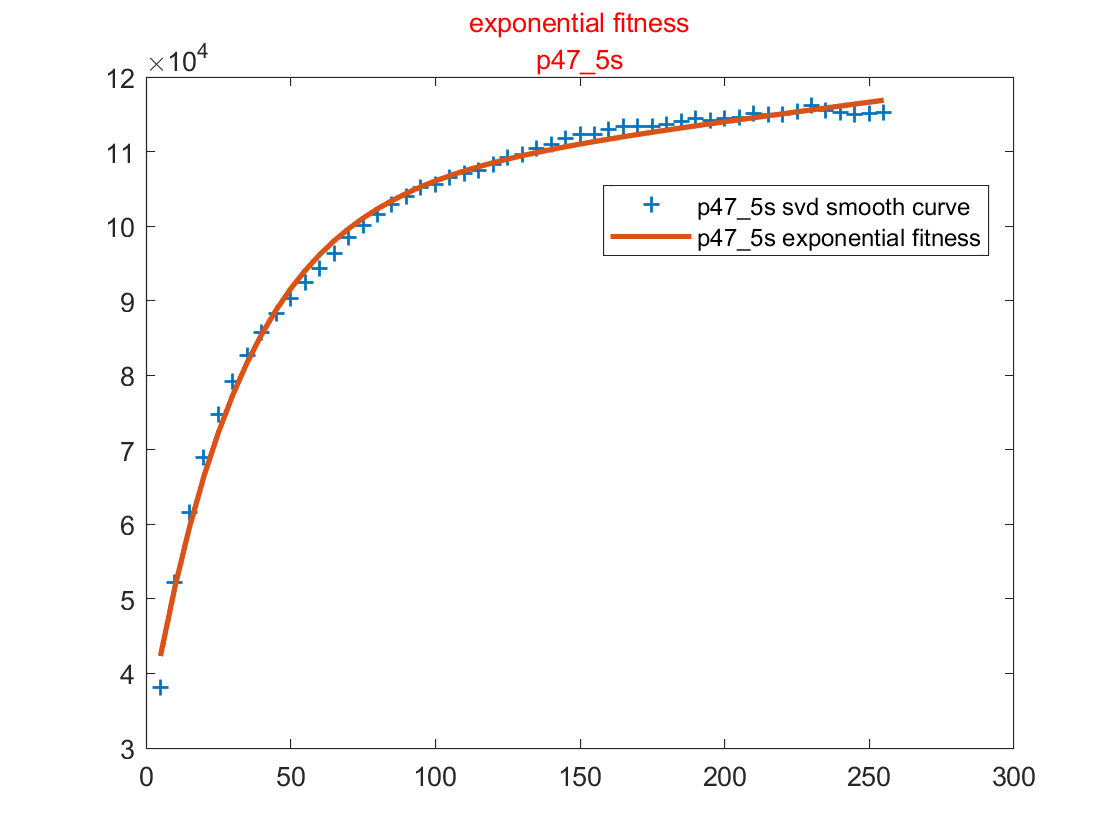

%for i=1:length(name_list)
    %cftool(time_scale,smoothed_curve(i,:))
%end
n_fit=3;
fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;
figure
plot(time_scale,smoothed_curve(n_fit,:),'+',"LineWidth",1)
hold on
plot(time_scale,fun(a,time_scale),'LineWidth',2)
title({['exponential fitness'],[num2str(name_list(n_fit)),'\_',num2str(experiment_interval),'s']},'Color','r','FontSize',10)
legend([num2str(name_list(n_fit)),'\_',num2str(experiment_interval),'s svd smooth curve'],[num2str(name_list(n_fit)),'\_',num2str(experiment_interval),'s exponential fitness'],"Location","best")

## Saving

saving_location='C:\Users\zhouquan\OneDrive\research\scrips\processed_data';
for i=1:length(name_list)
    smoothed_one_curve=smoothed_curve(i,:);
    save([saving_location,'\svd smooth data ',char(name_list(i)),'_',num2str(experiment_interval),'s'],'smoothed_one_curve')
    
    if i==10
        expomential_fitness_data=fun(a,time_scale);
        save([saving_location,'\expomential fitness data ',char(name_list(i)),'_',num2str(experiment_interval),'s'],'expomential_fitness_data')
    end
end